## Histograms for $P_{Y_{N}$

Number of draws (m) = 10000

rng(0);
m = 10000; 

for $N=2$

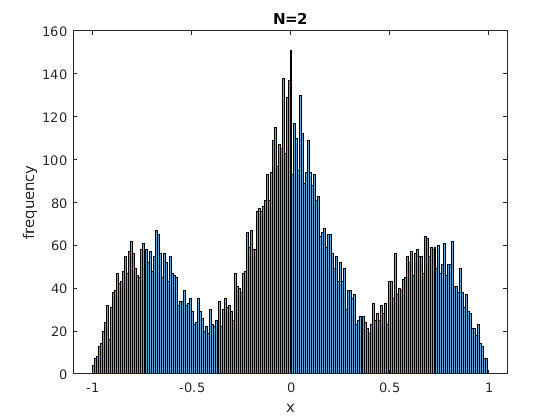

x = 2;
final = aver(x,m);
histogram(final,200);
title("N=2")
xlabel("x")
ylabel("frequency")

for $N=4$

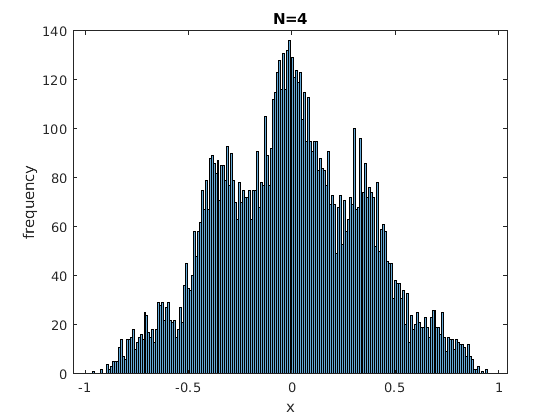

figure;
x = x*2;
final = aver(x,m);
histogram(final,200);
title("N=4")
xlabel("x")
ylabel("frequency")

for $N=8$

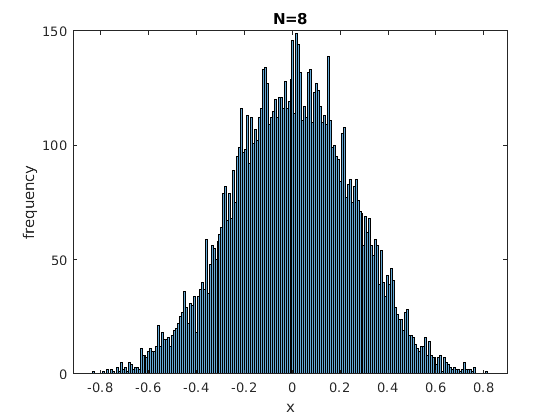

figure;
x = x*2;
final = aver(x,m);
histogram(final,200);
title("N=8")
xlabel("x")
ylabel("frequency")

for $N=16
$

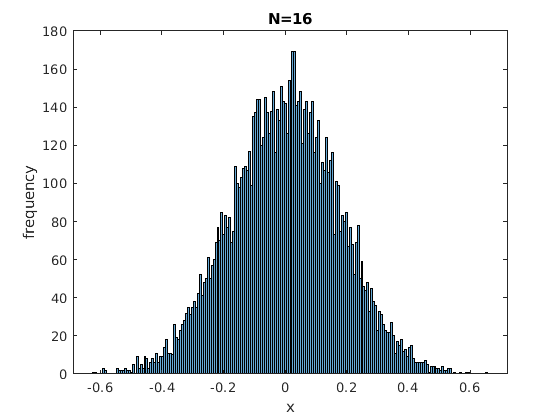

figure;
x = x*2;
final = aver(x,m);
histogram(final,200);
title("N=16")
xlabel("x")
ylabel("frequency")

for $N=32$

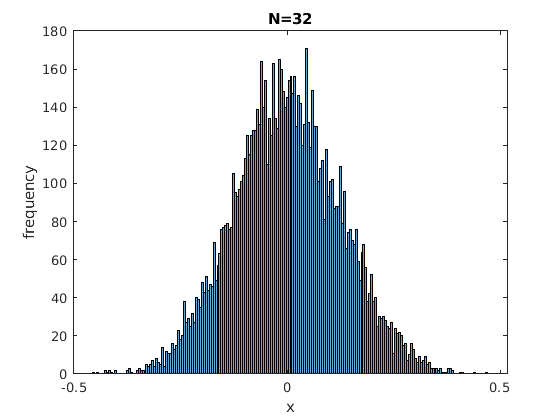

figure;
x = x*2;
final = aver(x,m);
histogram(final,200);
title("N=32")
xlabel("x")
ylabel("frequency")

for $N=64$

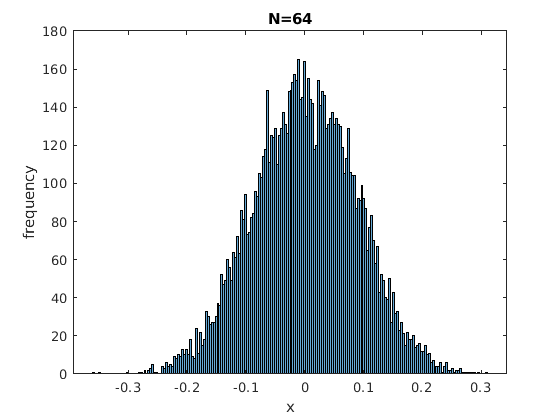

figure;
x = x*2;
final = aver(x,m);
histogram(final,200);
title("N=64")
xlabel("x")
ylabel("frequency")

Definition of function $\texttt{aver(.)}$ is given below.

It is a general function, can be used for any value of $N$

function avg = aver(n,m)
    avg = rand(n,m);
    for i=1:1:m
        for j = 1:1:n
            if avg(j,i) > 0.5
                avg(j,i) = sqrt(2*avg(j,i) - 1);
            else
                avg(j,i) = -1*(sqrt(1-2*avg(j,i)));
            end
        end
    end
    avg = sum(avg,1);
    avg = avg./n;
end

